# Ensemble Learning

load heartdisease
HD = heartdataAll.HeartDisease; % Extract the response variable

rng(1234)
part = cvpartition(HD,'KFold',10); % Make a partition for evaluation

Convert categorical variables to numeric dummy variables

[heartdataAll_dum, predictorNames_dum]=cattable2mat(heartdataAll)

'cattable2mat'을(를) 현재 폴더 또는 MATLAB 경로에서 찾을 수 없지만 다음 위치에 있습니다.
 C:\Users\hmc12\OneDrive\Documents\MATLAB\Week13
    C:\Users\hmc12\OneDrive\Documents\MATLAB\Week14

MATLAB 현재 폴더 변경 또는 해당 폴더를 MATLAB 경로에 추가.

## 1. Build an ensemble of 'bagging' trees

Bag: Bootstrapped aggregation, one of the popular methods along with 'Boosting'.

For various methods and their supported problems, see the documentation below.

doc ensemble algorithms

A single tree

rng(1234)
mdlTree = fitctree(heartdataAll_dum,HD,'CVPartition',part);
treeLoss=kfoldLoss(mdlTree)

treeLoss = 0.2834

An ensemble trees

mdlEnsembleTree=fitcensemble(heartdataAll_dum,HD,'Method','Bag','NumLearningCycles',100,'CVPartition',part);

mdlEnsembleTree =   ClassificationPartitionedEnsemble
    CrossValidatedModel: 'Bag'
         PredictorNames: {1×35 cell}
           ResponseName: 'Y'
        NumObservations: 427
                  KFold: 10
              Partition: [1×1 cvpartition]
      NumTrainedPerFold: [100 100 100 100 100 100 100 100 100 100]
             ClassNames: [false    true]
         ScoreTransform: 'none'


  Properties, Methods


ensembleTreeLoss=kfoldLoss(mdlEnsembleTree)

ensembleTreeLoss = 0.1874

## 2. Build an ensemble of 'Subspace' k-NN

A single kNN with options

rng(1234)
mdlKNN=fitcknn(heartdataAll_dum,HD,'NumNeighbors',5,'Distance','euclidean','CVPartition',part)

mdlKNN =   ClassificationPartitionedModel
    CrossValidatedModel: 'KNN'
         PredictorNames: {1×35 cell}
           ResponseName: 'Y'
        NumObservations: 427
                  KFold: 10
              Partition: [1×1 cvpartition]
             ClassNames: [false    true]
         ScoreTransform: 'none'


  Properties, Methods


KNNLose=kfoldLoss(mdlKNN)

KNNLose = 0.1991

An ensemble kNN classifiers with options. For the options, use a learner's template.

knnmodel=templateKNN('NumNeighbors',5,'Distance','euclidean');

knnmodel = 피팅할 템플릿 대상 classification KNN.

       NumNeighbors: 5
           NSMethod: ''
           Distance: 'euclidean'
         BucketSize: ''
        IncludeTies: []
     DistanceWeight: []
          BreakTies: []
           Exponent: []
                Cov: []
              Scale: []
    StandardizeData: []
            Version: 1
             Method: 'KNN'
               Type: 'classification'


mdlEnsembleKNN=fitcensemble(heartdataAll_dum,HD,'Method','Subspace',...
    'Learners',knnmodel,'NumLearningCycles',100,'CVPartition',part);
ensembleKNNLoss=kfoldLoss(mdlEnsembleKNN)

ensembleKNNLoss = 0.4333


 % Does it give a good result?
 

 rng(1234)
 idx=training(cvpartition(heartdataNum.HeartDisease,'HoldOut',0.2));
 tdata=heartdataNum(idx,:);
 vdata=heartdataNum(~idx,:);
 parta=cvpartition(heartdataNum.HeartDisease,'KFold',10);
 partt=cvpartition(tdata.HeartDisease,'KFold',10);

mdl =   ClassificationTree
           PredictorNames: {'Age'  'Cholesterol'  'ExerciseDuration'  'METs'  'RestingHeartRate'  'RestingSystolic'  'RestingDiastolic'  'MaxHeartRate'  'PeakExSystolic'  'PeakExDiastolic'  'InducedSTDep'}
             ResponseName: 'HeartDisease'
    CategoricalPredictors: []
               ClassNames: [false    true]
           ScoreTransform: 'none'
          NumObservations: 342


  Properties, Methods


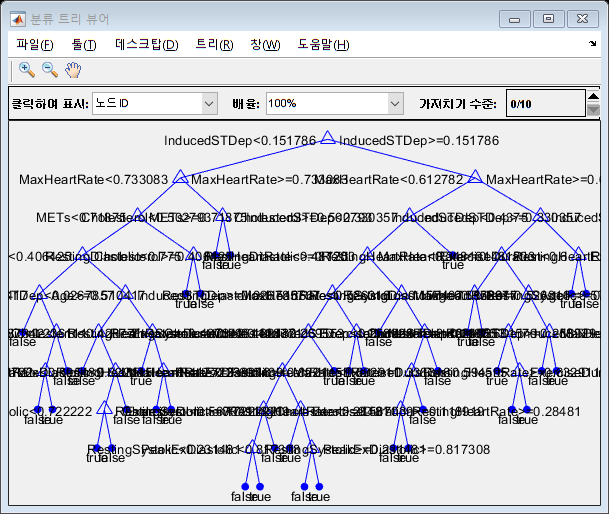

mdl =   ClassificationTree
           PredictorNames: {'Age'  'Cholesterol'  'ExerciseDuration'  'METs'  'RestingHeartRate'  'RestingSystolic'  'RestingDiastolic'  'MaxHeartRate'  'PeakExSystolic'  'PeakExDiastolic'  'InducedSTDep'}
             ResponseName: 'HeartDisease'
    CategoricalPredictors: []
               ClassNames: [false    true]
           ScoreTransform: 'none'
          NumObservations: 342


  Properties, Methods


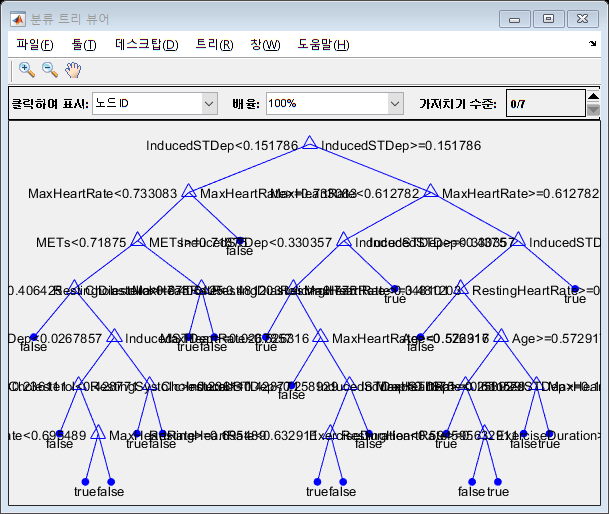

rng(1234)